# run ryan5_model_incremetal_learning_data

% load_data = false
 load_data = true

load_data = logical
   1



if load_data == true
    load ryan5_battery_dataset.mat
    load ryan5_data.mat
    load ryan5_data_for_test.mat
end


clear battery_testset_org  battery_testset  IcFull  IdFull TcFull TdFull VcFull VdFull Ic Id Tc Td Vc Vd
%clear xnorm_Ic xnorm_Ic_RUL xnorm_Ic_SOH 

format default

% load('ryan5_data_for_test.mat','testdata_base_batNum'		);
% load('ryan5_data_for_test.mat','testdata_shortRul_batNum'	);
% load('ryan5_data_for_test.mat','testdata_longRul_batNum'	);
% load('ryan5_data_for_test.mat','testdata1_batNum_str'		);
% load('ryan5_data_for_test.mat','testdata2_batNum_str'		);
% load('ryan5_data_for_test.mat','testdata3_batNum_str'      );
% 
% load('ryan5_data_for_test.mat','ryan5_change_bs_Rul');
% load('ryan5_data_for_test.mat','ryan5_change_bl_Rul');
% load('ryan5_data_for_test.mat','ryan5_change_ss_Rul');
% load('ryan5_data_for_test.mat','ryan5_change_bb_Rul');
% load('ryan5_data_for_test.mat','ryan5_change_ll_Rul');

use_testdata1 = false

use_testdata1 = logical
   0


% use_testdata2 = false
use_testdata3 = false 

use_testdata3 = logical
   0



% use_testdata1 = true
use_testdata2 = true 

use_testdata2 = logical
   1


% use_testdata3 = true 

% use_testdata_for_learning = true 
% use_bestMatchData_for_learning = false 
% use_poorMatchData_for_learning = false 


if use_testdata1 == true
    testdata_str = "Test Data 1";
    ytrain = ynorm_soh_ref;
    xtrain = xnorm_soh_ref;
    Ytrain = Y_soh_ref;
    Ytrain_soh = Y_soh_ref;

    ytrain_best = testdata1_best_soh_norm;
    xtrain_best = testdata1_best_Vd_norm;
    Ytrain_best = testdata1_best_soh;
    Ytrain_soh_best = testdata1_best_soh;

    ynorm_similar_1 = ynorm_soh_big;
    ynorm_similar_2 = ynorm_soh_small;
    xnorm_similar_1 = xnorm_soh_big;
    xnorm_similar_2 = xnorm_soh_small;
    Y_soh_similar_1 = Y_soh_big;
    Y_soh_similar_2 = Y_soh_small;   
    Y_similar_1 = Y_soh_big;
    Y_similar_2 = Y_soh_small ;

    scenario3_1_xtrain = testdata1_best_Vd_norm ;
    scenario3_1_ytrain = testdata1_best_soh_norm ;
    scenario3_1_Ytrain = testdata1_best_soh ;
    scenario3_1_Ytrain_SOH = testdata1_best_soh;
    
    scenario3_2_xtrain = testdata1_poor_Vd_norm ;
    scenario3_2_ytrain = testdata1_poor_soh_norm ;
    scenario3_2_Ytrain = testdata1_poor_soh ;
    scenario3_2_Ytrain_SOH = testdata1_poor_soh;

    testdata_best_soh_norm = testdata1_best_soh_norm;
    testdata_poor_soh_norm = testdata1_poor_soh_norm;
end 


if use_testdata2 == true
    testdata_str = "Test Data 2";
    ytrain = testdata2_base_soh_norm; %ynorm_ref_to_small;
    xtrain = xnorm_ref_to_small;
    Ytrain = Y_ref_to_small;
    Ytrain_soh = Y_soh_ref_to_small;

    ytrain_best = testdata2_best_soh_norm;
    xtrain_best = testdata2_best_Vd_norm;
    Ytrain_best = testdata2_best_soh;
    Ytrain_soh_best = testdata2_best_soh;

    ynorm_similar_1 = ynorm_soh_big;
    ynorm_similar_2 = ynorm_soh_small;
    Y_soh_similar_1 = Y_soh_soh_big;
    Y_soh_similar_2 = Y_soh_soh_small;   
    Y_similar_1 = Y_soh_big;
    Y_similar_2 = Y_soh_small ;

    scenario3_1_xtrain = testdata2_best_Vd_norm ;
    scenario3_1_ytrain = testdata2_best_soh_norm ;
    scenario3_1_Ytrain = testdata2_best_soh ;
    scenario3_1_Ytrain_SOH = testdata2_best_soh;
    
    scenario3_2_xtrain = testdata2_poor_Vd_norm ;
    scenario3_2_ytrain = testdata2_poor_soh_norm ;
    scenario3_2_Ytrain = testdata2_poor_soh ;
    scenario3_2_Ytrain_SOH = testdata2_poor_soh;    

    testdata_best_soh_norm = testdata2_best_soh_norm;
    testdata_poor_soh_norm = testdata2_poor_soh_norm;
end

Unrecognized function or variable 'ynorm_soh_big'.


if use_testdata3 == true
    testdata_str = "Test Data 3";
    ytrain = ynorm_soh_ref_to_small
    xtrain = xnorm_soh_ref_to_big
    Ytrain = Y_soh_ref_to_big
    Ytrain_soh = Y_soh_ref_to_big

    ytrain_best = testdata3_best_soh_norm;
    xtrain_best = testdata3_best_Vd_norm;
    Ytrain_best = testdata3_best_soh;
    Ytrain_soh_best = testdata3_best_soh;

    ynorm_similar_1 = ynorm_big;
    ynorm_similar_2 = ynorm_small;
    Y_soh_similar_1 = Y_soh_big;
    Y_soh_similar_2 = Y_soh_small;   
    Y_similar_1 = Y_big;
    Y_similar_2 = Y_small ;

    scenario3_1_xtrain = testdata3_best_Vd_norm ;
    scenario3_1_ytrain = testdata3_best_soh_norm ;
    scenario3_1_Ytrain = testdata3_best_soh ;
    scenario3_1_Ytrain_SOH = testdata3_best_soh;
    
    scenario3_2_xtrain = testdata3_poor_Vd_norm ;
    scenario3_2_ytrain = testdata3_poor_soh_norm ;
    scenario3_2_Ytrain = testdata3_poor_soh ;
    scenario3_2_Ytrain_SOH = testdata3_poor_soh;

    testdata_best_soh_norm = testdata3_best_soh_norm;
    testdata_poor_soh_norm = testdata3_poor_soh_norm;
end

total = length(ytrain)
pre = 50;
future = total - pre
scenario3_xtrain = xtrain ;
scenario3_ytrain = ytrain ;
scenario3_Ytrain = Ytrain ;
scenario3_Ytrain_SOH = Ytrain_soh;

scenario1_xtrain = xtrain(1:pre,:);
scenario1_ytrain = ytrain(1:pre,:);
scenario1_Ytrain = Ytrain(1:pre,:);
scenario2_xtrain = xtrain(pre+1:end,:);
scenario2_ytrain = ytrain(pre+1:end,:);
scenario2_Ytrain = Ytrain(pre+1:end,:);

scenario1_Ytrain_SOH = Ytrain_soh(1:pre,:);
scenario2_Ytrain_SOH = Ytrain_soh(pre+1:end,:);



n = numel(ytrain);
numObsPerChunk = 5;


maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);


Mdl = incrementalRegressionLinear(  ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',10, ...
    'Learner','leastsquares', ...
    'Metrics',{ 'mse' })

Mdl =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [0×1 double]
                 Bias: 0
              Learner: 'leastsquares'


  Properties, Methods



% Preallocation
 %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    

% Incremental fitting
rng("default"); % For reproducibility
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ;    
    Mdl = updateMetricsAndFit(Mdl,xtrain(idx,:),ytrain(idx));
    Mdl.Beta;
    Mdl.Bias;
    mse_val{j,:} = Mdl.Metrics{"MeanSquaredError",:};
    beta10(j + 1) = Mdl.Beta(10);
end

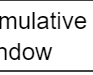

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

[scenario1and2_mdl,FitInfo] = ...
    fitrlinear(scenario1_xtrain,scenario1_ytrain,"learner","leastsquares")

scenario1and2_mdl =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: 0.2473
               Lambda: 0.0200
              Learner: 'leastsquares'


  Properties, Methods


FitInfo = struct with fields:
                    Lambda: 0.0200
                 Objective: 7.4262e-05
            IterationLimit: 1000
             NumIterations: 8
              GradientNorm: 1.6935e-05
         GradientTolerance: 1.0000e-06
      RelativeChangeInBeta: 7.8861e-05
             BetaTolerance: 1.0000e-04
             DeltaGradient: []
    DeltaGradientTolerance: []
           TerminationCode: 1
         TerminationStatus: {'Tolerance on coefficients satisfied.'}
                   History: []
                   FitTime: 0.0011
                    Solver: {'bfgs'}


Beta = scenario1and2_mdl.Beta

Beta =    -0.0010
   -0.0008
   -0.0008
   -0.0007
   -0.0007
   -0.0006
   -0.0006
   -0.0006
   -0.0005
   -0.0004


Bias = scenario1and2_mdl.Bias

Bias = 0.2473

X_input = scenario1_xtrain

X_input =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209    0.0010    0.

Y_predict_from_calc = scenario1_xtrain * scenario1and2_mdl.Beta + scenario1and2_mdl.Bias

Y_predict_from_calc =     0.2488
    0.2487
    0.2487
    0.2487
    0.2486
    0.2486
    0.2486
    0.2486
    0.2485
    0.2485


Y_predict_from_predict_function = predict(scenario1and2_mdl,scenario1_xtrain)

Y_predict_from_predict_function =     0.2488
    0.2487
    0.2487
    0.2487
    0.2486
    0.2486
    0.2486
    0.2486
    0.2485
    0.2485



scenario1_yhat_calc = scenario1_xtrain(1,:) * scenario1and2_mdl.Beta + scenario1and2_mdl.Bias

scenario1_yhat_calc = 0.2488

scenario1_yhat_predict = predict(scenario1and2_mdl,scenario1_xtrain(1,:))

scenario1_yhat_predict = 0.2488

# 시나리오 1.

title_with_performance = 1×2 string array
    "Scenario 1 (Test Data 2)"    "( RMSE = 14.09  MAPE = 4.21 )"


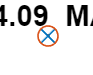

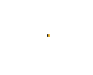

result_scenario1_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    14.091    4.2072


scenario1_rmse_2digit = '14.09'

scenario1_mape_2digit = '4.21'

scenario_str = "Scenario 1";
title_str = scenario_str +" (" + testdata_str + ")";
scenario1_yhat = predict(scenario1and2_mdl,scenario1_xtrain);

scenario1_Yhat = minmax_denorm_with_param(scenario1_yhat,ymin_RUL,yrate_RUL);
[scenario1_rmse,scenario1_mape,scenario1_ape,ae_scenario1,err_scenario1] = eval_perfomance(scenario1_Ytrain,scenario1_Yhat);
[result_scenario1_summary,scenario1_rmse_2digit,scenario1_mape_2digit] = ryan5_util_plot_scenario_rmse_mape( scenario1_Ytrain, scenario1_Yhat, scenario1_ape, scenario1_Ytrain_SOH,  title_str, false, scenario1_rmse, scenario1_mape)

# 시나리오 2.

title_with_performance = 1×2 string array
    "Scenario 2 (Test Data 2)"    "( RMSE = 153.55  MAPE = 434.68 )"


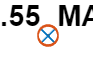

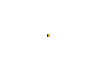

result_scenario2_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    153.55    434.68


scenario2_rmse_2digit = '153.55'

scenario2_mape_2digit = '434.68'

scenario_str = "Scenario 2";
title_str = scenario_str +" (" + testdata_str + ")";
scenario2_yhat = predict(scenario1and2_mdl,scenario2_xtrain);

scenario2_Yhat = minmax_denorm_with_param(scenario2_yhat,ymin_RUL,yrate_RUL);
[scenario2_rmse,scenario2_mape,scenario2_ape,scenario2_ae,err_scenario2] = eval_perfomance(scenario2_Ytrain, scenario2_Yhat);
[result_scenario2_summary,scenario2_rmse_2digit,scenario2_mape_2digit]  = ryan5_util_plot_scenario_rmse_mape( scenario2_Ytrain, scenario2_Yhat, scenario2_ape, scenario2_Ytrain_SOH,  title_str, false, scenario2_rmse, scenario2_mape)

load('ryan5_data_for_test.mat', 'scenario3_mdl')
%global scenario3_mdl;

# 시나리오 3. 

title_with_performance = 1×2 string array
    "Scenario 3 (Test Data 2)"    "( RMSE = 63.22  MAPE = 31.84 )"


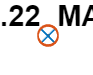

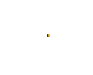

result_scenario3_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    63.216    31.835


scenario3_rmse_2digit = '63.22'

scenario3_mape_2digit = '31.84'

scenario_str = "Scenario 3";
title_str = scenario_str +" (" + testdata_str + ")";
scenario3_yhat = predict(scenario3_mdl,scenario3_xtrain);

scenario3_Yhat = minmax_denorm_with_param(scenario3_yhat,ymin_RUL,yrate_RUL);
[scenario3_rmse,scenario3_mape,scenario3_ape,scenario3_ae,err_scenario3] = ...
    eval_perfomance(scenario3_Ytrain, scenario3_Yhat);
[result_scenario3_summary,scenario3_rmse_2digit,scenario3_mape_2digit]= ...
    ryan5_util_plot_scenario_rmse_mape( scenario3_Ytrain, scenario3_Yhat, scenario3_ape, scenario3_Ytrain_SOH,  title_str, false, scenario3_rmse, scenario3_mape)


% yhat = predict(scenario3_mdl,xtrain(1,:));
% scenario3_mdl.Beta ;
% scenario3_mdl.Bias ;
% yhat_cals = xtrain(1,:) * scenario3_mdl.Beta  +  scenario3_mdl.Bias
scenario3_rmse,scenario3_mape

scenario3_rmse = 63.2158

scenario3_mape = 31.8353

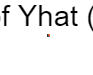

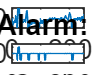


ryan5_util_plot_change_detect( scenario3_Yhat, title_str);

# 시나리오 3_1. -  best similar

title_with_performance = 1×2 string array
    "Scenario 3-1 (Test Data 2) (Ref Data 2)"    "( RMSE = 197.51  MAPE = 109874.84 )"


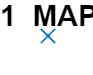

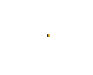

result_scenario3_1_summary = 1×2 table
     RMSE        MAPE   
    ______    __________

    197.51    1.0987e+05


scenario3_1_rmse_2digit = '197.51'

scenario3_1_mape_2digit = '109874.84'

scenario_str = "Scenario 3-1";
title_str = scenario_str +" (" + testdata_str + ") (Ref Data 2)";
scenario3_1_yhat = predict(scenario3_mdl,scenario3_1_xtrain);
scenario3_1_Yhat = minmax_denorm_with_param(scenario3_1_yhat,ymin_RUL,yrate_RUL);

[scenario3_1_rmse,scenario3_1_mape,scenario3_1_ape,scenario3_1_ae,err_best_scenario3] = ...
    eval_perfomance(scenario3_1_ytrain,scenario3_1_Yhat);
[result_scenario3_1_summary,scenario3_1_rmse_2digit,scenario3_1_mape_2digit]= ryan5_util_plot_scenario_rmse_mape( scenario3_1_Ytrain, scenario3_1_Yhat, scenario3_1_ape, scenario3_1_Ytrain_SOH,  title_str, false, scenario3_1_rmse, scenario3_1_mape)

scenario3_1_rmse,scenario3_1_mape

scenario3_1_rmse = 197.5100

scenario3_1_mape = 1.0987e+05

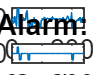


ryan5_util_plot_change_detect( scenario3_1_Yhat,title_str);

# 시나리오 3_2. -  poor similar

title_with_performance = 1×2 string array
    "Scenario 3-2 (Test Data 2) (Ref Data 3)"    "( RMSE = 26.43  MAPE = 24.03 )"


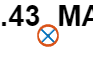

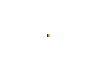

result_scenario3_2_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    26.429    24.035


scenario3_2_rmse_2digit = '26.43'

scenario3_2_mape_2digit = '24.03'

scenario_str = "Scenario 3-2";
title_str = scenario_str +" (" + testdata_str + ") (Ref Data 3)";
scenario3_2_yhat = predict(scenario3_mdl,scenario3_2_xtrain);

scenario3_2_Yhat = minmax_denorm_with_param(scenario3_2_yhat,ymin_RUL,yrate_RUL);
[scenario3_2_rmse,scenario3_2_mape,scenario3_2_ape,scenario3_2_ae,err_poor_scenario3] = ...
    eval_perfomance(scenario3_2_Ytrain,scenario3_2_Yhat);
[result_scenario3_2_summary,scenario3_2_rmse_2digit,scenario3_2_mape_2digit]= ryan5_util_plot_scenario_rmse_mape( scenario3_2_Ytrain, scenario3_2_Yhat, scenario3_2_ape, scenario3_2_Ytrain_SOH,  title_str, false, scenario3_2_rmse, scenario3_2_mape)

scenario3_2_rmse,scenario3_2_mape

scenario3_2_rmse = 26.4287

scenario3_2_mape = 24.0350

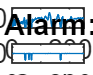


ryan5_util_plot_change_detect( scenario3_2_Yhat, title_str);

# 시나리오 4. 트레이닝에 사용된 값을 관찰값으로 

scenario_str = "Scenario 4"

scenario_str = "Scenario 4"

title_str = scenario_str +" (" + testdata_str + ")";


scenario4_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_y'

updatePolicy = 'use_y'

scenario4_xnorm = xtrain;
scenario4_ynorm = ytrain;
scenario4_Y = Ytrain;
scenario4_Y_soh = Ytrain_soh;
scenario4_ynorm_legacy = ytrain;

n=length(scenario4_ynorm)

n = 250

[scenario4_mdl, scenario4_yhat, scenario4_yhat_cnt]= ...
    ryan5_run_inc_learning(scenario4_mdl,n,updatePolicy,scenario4_xnorm,scenario4_ynorm,scenario4_ynorm_legacy)

scenario4_mdl =   incrementalRegressionLinear

               IsWarm: 1
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0672
              Learner: 'leastsquares'


  Properties, Methods


scenario4_yhat =     0.2604
    0.2559
    0.2534
    0.2499
    0.2475
    0.2690
    0.2674
    0.2668
    0.2637
    0.2611


scenario4_yhat_cnt = 250

scenario4_Yhat = minmax_denorm_with_param(scenario4_yhat,ymin_RUL,yrate_RUL);
[scenario4_rmse,scenario4_mape,scenario4_ape,scenario4_ae,scenario4_error] = ...
    eval_perfomance(scenario4_Y,scenario4_Yhat);
scenario4_rmse, scenario4_mape

scenario4_rmse = 6.4187

scenario4_mape = 3.8271

title_with_performance = 1×2 string array
    "Scenario 4 (Test Data 2)"    "( RMSE = 6.42  MAPE = 3.83 )"


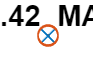

result_scenario4_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    6.4187    3.8271


scenario4_rmse_2digit = '6.42'

scenario4_mape_2digit = '3.83'

[result_scenario4_summary,scenario4_rmse_2digit,scenario4_mape_2digit]= ryan5_util_plot_scenario_rmse_mape( scenario4_Y, scenario4_Yhat, scenario4_ape, scenario4_Y_soh,  title_str, false,scenario4_rmse, scenario4_mape)

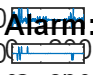


ryan5_util_plot_change_detect( scenario4_Yhat, title_str);

# 시나리오 4_1. 오차가 큰 비슷한 값 패턴에서 RUL을 추출해서 관찰값으로 - 잘못된 예측

scenario_str = "Scenario 4-1"

scenario_str = "Scenario 4-1"

title_str = scenario_str +" (" + testdata_str + ") (Ref Data 1)";

scenario4_1_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_yref'

updatePolicy = 'use_yref'

scenario4_1_xnorm = xtrain;
scenario4_1_ynorm = ytrain;
scenario4_1_Y = Ytrain;
scenario4_1_Y_soh = Ytrain_soh;
scenario4_1_ynorm_ref = ynorm_small; % set reference to learning

n=length(scenario4_1_ynorm);
[scenario4_1_mdl, scenario4_1_yhat, scenario4_1_yhat_cnt]= ...
    ryan5_run_inc_learning(...
    scenario4_1_mdl,n,updatePolicy,scenario4_1_xnorm,scenario4_1_ynorm,...
    scenario4_1_ynorm_ref);

scenario4_1_Yhat = minmax_denorm_with_param(scenario4_1_yhat,ymin_RUL,yrate_RUL);

[scenario4_1_rmse,scenario4_1_mape,scenario4_1_ape,scenario4_1_ae,scenario4_1_error] = ...
    eval_perfomance(...
    scenario4_1_Y(1:scenario4_1_yhat_cnt),...
    scenario4_1_Yhat(1:scenario4_1_yhat_cnt));

scenario4_1_rmse, scenario4_1_mape

scenario4_1_rmse = 177.1491

scenario4_1_mape = 73.6636

title_with_performance = 1×2 string array
    "Scenario 4-1 (Test Data 2) (Ref Data 1)"    "( RMSE = 177.15  MAPE = 73.66 )"


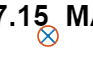

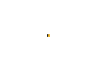

result_scenario4_1_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    177.15    73.664


scenario4_1_rmse_2digit = '177.15'

scenario4_1_mape_2digit = '73.66'


[result_scenario4_1_summary,scenario4_1_rmse_2digit,scenario4_1_mape_2digit]= ...
    ryan5_util_plot1_scenario_rmse_mape( ...
        scenario4_1_Y(1:scenario4_1_yhat_cnt), ...
        scenario4_1_Yhat(1:scenario4_1_yhat_cnt),...
        scenario4_1_ape(1:scenario4_1_yhat_cnt), ...
        scenario4_1_Y_soh(1:scenario4_1_yhat_cnt), ...
        scenario4_1_ynorm_ref(1:scenario4_1_yhat_cnt), ...
        title_str, false,scenario4_1_rmse, scenario4_1_mape)

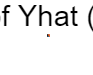

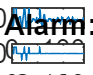


ryan5_util_plot_change_detect( scenario4_1_Yhat, title_str);

# 시나리오 4_2. 가장 비슷한 패턴의 데이타에서 값을 가져와 관측값으로 사용 

scenario_str = "Scenario 4-2"

scenario_str = "Scenario 4-2"

title_str = scenario_str +" (" + testdata_str + ") (Ref Data 2)";

scenario4_2_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_yref'

updatePolicy = 'use_yref'


scenario4_2_xnorm = xtrain;
scenario4_2_ynorm = ytrain;
scenario4_2_Y = Ytrain;
scenario4_2_Y_soh = Ytrain_soh;
scenario4_2_ynorm_ref = testdata_best_soh_norm; % set reference to learning

n=length(scenario4_2_ynorm);
[scenario4_2_mdl, scenario4_2_yhat, scenario4_2_yhat_cnt]= ...
    ryan5_run_inc_learning(...
    scenario4_2_mdl,n,updatePolicy,scenario4_2_xnorm,scenario4_2_ynorm,...
    scenario4_2_ynorm_ref);

scenario4_2_Yhat = minmax_denorm_with_param(scenario4_2_yhat,ymin_RUL,yrate_RUL);

[scenario4_2_rmse,scenario4_2_mape,scenario4_2_ape,scenario4_2_ae,scenario4_2_error] = ...
    eval_perfomance(...
    scenario4_2_Y(1:scenario4_2_yhat_cnt),...
    scenario4_2_Yhat(1:scenario4_2_yhat_cnt));

scenario4_2_rmse, scenario4_2_mape

scenario4_2_rmse = 16.7799

scenario4_2_mape = 11.3257

title_with_performance = 1×2 string array
    "Scenario 4-2 (Test Data 2) (Ref Data 2)"    "( RMSE = 16.78  MAPE = 11.33 )"


result_scenario4_2_summary = 1×2 table
    RMSE      MAPE 
    _____    ______

    16.78    11.326


scenario4_2_rmse_2digit = '16.78'

scenario4_2_mape_2digit = '11.33'

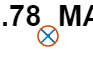


[result_scenario4_2_summary,scenario4_2_rmse_2digit,scenario4_2_mape_2digit]= ...
    ryan5_util_plot1_scenario_rmse_mape( ...
        scenario4_2_Y(1:scenario4_2_yhat_cnt), ...
        scenario4_2_Yhat(1:scenario4_2_yhat_cnt),...
        scenario4_2_ape(1:scenario4_2_yhat_cnt), ...
        scenario4_2_Y_soh(1:scenario4_2_yhat_cnt), ...
        scenario4_2_ynorm_ref(1:scenario4_2_yhat_cnt), ...
        title_str, false,scenario4_2_rmse, scenario4_2_mape)


ryan5_util_plot_change_detect( scenario4_2_Yhat, title_str);

# 시나리오 4_3. 서버에 데이타가 붖족해서 대충 비슷한 패턴의 데이타에서 값을 가져와 관측값으로 사용 

scenario_str = "Scenario 4-3"

scenario_str = "Scenario 4-3"

title_str = scenario_str +" (" + testdata_str + ") (Ref Data 3)";

scenario4_3_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_yref'

scenario4_3_xnorm = xtrain;
scenario4_3_ynorm = ytrain;
scenario4_3_Y = Ytrain;
scenario4_3_Y_soh = Ytrain_soh;
scenario4_3_ynorm_ref = testdata_poor_soh_norm; 

n=length(scenario4_3_ynorm);
[scenario4_3_mdl, scenario4_3_yhat, scenario4_3_yhat_cnt]= ...
    ryan5_run_inc_learning(...
    scenario4_3_mdl,n,updatePolicy,scenario4_3_xnorm,scenario4_3_ynorm,...
    scenario4_3_ynorm_ref);

scenario4_3_Yhat = minmax_denorm_with_param(scenario4_3_yhat,ymin_RUL,yrate_RUL);

[scenario4_3_rmse,scenario4_3_mape,scenario4_3_ape,scenario4_3_ae,scenario4_3_error] = ...
    eval_perfomance(...
    scenario4_3_Y(1:scenario4_3_yhat_cnt),...
    scenario4_3_Yhat(1:scenario4_3_yhat_cnt));

scenario4_3_rmse, scenario4_3_mape

[result_scenario4_3_summary,scenario4_3_rmse_2digit,scenario4_3_mape_2digit]= ...
    ryan5_util_plot1_scenario_rmse_mape( ...
        scenario4_3_Y(1:scenario4_3_yhat_cnt), ...
        scenario4_3_Yhat(1:scenario4_3_yhat_cnt),...
        scenario4_3_ape(1:scenario4_3_yhat_cnt), ...
        scenario4_3_Y_soh(1:scenario4_3_yhat_cnt), ...
        scenario4_3_ynorm_ref(1:scenario4_3_yhat_cnt), ...
        title_str, false,scenario4_3_rmse, scenario4_3_mape)

ryan5_util_plot_change_detect( scenario4_3_Yhat, title_str);

# 시나리오 5. 자신의 예측값을 관측값으로 사용 => 학습율 0.002

scenario_str = "Scenario 5"
title_str = scenario_str +" (" + testdata_str + ") (Learn Rate=0.002)";


scenario5_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_own_predict'
scenario5_xnorm = xtrain;
scenario5_ynorm = ytrain;
scenario5_Y = Ytrain;
scenario5_Y_soh = Ytrain_soh;
scenario5_ynorm_ref = ytrain; % set reference to learning

n=length(scenario5_ynorm);
[scenario5_mdl, scenario5_yhat, scenario5_yhat_cnt]= ...
    ryan5_run_inc_learning(...
    scenario5_mdl,n,updatePolicy,scenario5_xnorm,scenario5_ynorm,...
    scenario5_ynorm_ref);

scenario5_Yhat = minmax_denorm_with_param(scenario5_yhat,ymin_RUL,yrate_RUL);

[scenario5_rmse,scenario5_mape,scenario5_ape,scenario5_ae,scenario5_error] = ...
    eval_perfomance(...
    scenario5_Y(1:scenario5_yhat_cnt),...
    scenario5_Yhat(1:scenario5_yhat_cnt));

scenario5_rmse, scenario5_mape

[result_scenario5_summary,scenario5_rmse_2digit,scenario5_mape_2digit]= ryan5_util_plot_scenario_rmse_mape( ...
    scenario5_Y(1:scenario5_yhat_cnt), ...
    scenario5_Yhat(1:scenario5_yhat_cnt),...
    scenario5_ape(1:scenario5_yhat_cnt), ...
    scenario5_Y_soh(1:scenario5_yhat_cnt), ...
    title_str, false,scenario5_rmse, scenario5_mape)

# 시나리오 5_1. 자신의 예측값을 관측값으로 사용 => 학습율 0.01

scenario_str = "Scenario 5-1"
title_str = scenario_str +" (" + testdata_str + ") (Learn Rate=0.01)";


scenario5_1_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.01, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_own_predict'
scenario5_1_xnorm = xtrain;
scenario5_1_ynorm = ytrain;
scenario5_1_Y = Ytrain;
scenario5_1_Y_soh = Ytrain_soh;
scenario5_1_ynorm_ref = ytrain; % set reference to learning

n=length(scenario5_1_ynorm);
[scenario5_1_mdl, scenario5_1_yhat, scenario5_1_yhat_cnt]= ...
    ryan5_run_inc_learning(...
    scenario5_1_mdl,n,updatePolicy,scenario5_1_xnorm,scenario5_1_ynorm,...
    scenario5_1_ynorm_ref);

scenario5_1_Yhat = minmax_denorm_with_param(scenario5_1_yhat,ymin_RUL,yrate_RUL);

[scenario5_1_rmse,scenario5_1_mape,scenario5_1_ape,scenario5_1_ae,scenario5_1_error] = ...
    eval_perfomance(...
    scenario5_1_Y(1:scenario5_1_yhat_cnt),...
    scenario5_1_Yhat(1:scenario5_1_yhat_cnt));

scenario5_1_rmse, scenario5_1_mape

[result_scenario5_1_summary,scenario5_1_rmse_2digit,scenario5_1_mape_2digit]= ryan5_util_plot_scenario_rmse_mape( ...
    scenario5_1_Y(1:scenario5_1_yhat_cnt), ...
    scenario5_1_Yhat(1:scenario5_1_yhat_cnt),...
    scenario5_1_ape(1:scenario5_1_yhat_cnt), ...
    scenario5_1_Y_soh(1:scenario5_1_yhat_cnt), ...
    title_str, false,scenario5_1_rmse, scenario5_1_mape)

# 시나리오 5_2. 자신의 예측값을 관측값으로 사용 => 학습율 0.1

scenario_str = "Scenario 5-2"
title_str = scenario_str +" (" + testdata_str + ") (Learn Rate=0.1)";

scenario5_2_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_own_predict'
scenario5_2_xnorm = xtrain;
scenario5_2_ynorm = ytrain;
scenario5_2_Y = Ytrain;
scenario5_2_Y_soh = Ytrain_soh;
scenario5_2_ynorm_ref = ytrain; % set reference to learning

n=length(scenario5_2_ynorm);
[scenario5_2_mdl, scenario5_2_yhat, scenario5_2_yhat_cnt]= ...
    ryan5_run_inc_learning(...
    scenario5_2_mdl,n,updatePolicy,scenario5_2_xnorm,scenario5_2_ynorm,...
    scenario5_2_ynorm_ref);

scenario5_2_Yhat = minmax_denorm_with_param(scenario5_2_yhat,ymin_RUL,yrate_RUL);

[scenario5_2_rmse,scenario5_2_mape,scenario5_2_ape,scenario5_2_ae,scenario5_2_error] = ...
    eval_perfomance(...
    scenario5_2_Y(1:scenario5_2_yhat_cnt),...
    scenario5_2_Yhat(1:scenario5_2_yhat_cnt));

scenario5_2_rmse, scenario5_2_mape

[result_scenario5_2_summary,scenario5_2_rmse_2digit,scenario5_2_mape_2digit]= ryan5_util_plot_scenario_rmse_mape( ...
    scenario5_2_Y(1:scenario5_2_yhat_cnt), ...
    scenario5_2_Yhat(1:scenario5_2_yhat_cnt),...
    scenario5_2_ape(1:scenario5_2_yhat_cnt), ...
    scenario5_2_Y_soh(1:scenario5_2_yhat_cnt), ...
    title_str, false,scenario5_2_rmse, scenario5_2_mape)

# 시나리오 6. 자신의 예측값과 확실한 관측값을 사용 사용 => 학습율 0.1

scenario_str = "Scenario 6"
title_str = scenario_str +" (" + testdata_str + ")";

scenario6_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_yref_and_own_predict'
scenario6_xnorm = xtrain;
scenario6_ynorm = ytrain;
scenario6_Y = Ytrain;
scenario6_Y_soh = Ytrain_soh;
scenario6_ynorm_ref = ytrain; % set reference to learning

n=length(scenario6_ynorm);
[scenario6_mdl, scenario6_yhat, scenario6_yhat_cnt]= ...
    ryan5_run_inc_learning(...
    scenario6_mdl,n,updatePolicy,scenario6_xnorm,scenario6_ynorm,...
    scenario6_ynorm_ref);

scenario6_Yhat = minmax_denorm_with_param(scenario6_yhat,ymin_RUL,yrate_RUL);

[scenario6_rmse,scenario6_mape,scenario6_ape,scenario6_ae,scenario6_error] = ...
    eval_perfomance(...
    scenario6_Y(1:scenario6_yhat_cnt),...
    scenario6_Yhat(1:scenario6_yhat_cnt));

scenario6_rmse, scenario6_mape

[result_scenario6_summary,scenario6_rmse_2digit,scenario6_mape_2digit]= ryan5_util_plot_scenario_rmse_mape( ...
    scenario6_Y(1:scenario6_yhat_cnt), ...
    scenario6_Yhat(1:scenario6_yhat_cnt),...
    scenario6_ape(1:scenario6_yhat_cnt), ...
    scenario6_Y_soh(1:scenario6_yhat_cnt), ...
    title_str, false,scenario6_rmse, scenario6_mape)

scenario4_rmse, scenario4_mape
scenario6_rmse, scenario6_mape


ryan5_util_plot_change_detect( scenario6_Yhat, title_str);

# 시나리오 6_1. 자신의 예측값과 오차가 큰 참조값을 관측값으로 사용 사용 => 학습율 0.1  시나리오 4_1과 비교

scenario_str = "Scenario 6-1"
title_str = scenario_str +" (" + testdata_str + ") (Ref Data 1)";

scenario6_1_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_yref_and_own_predict'
scenario6_1_xnorm = xtrain;
scenario6_1_ynorm = ytrain;
scenario6_1_Y = Ytrain;
scenario6_1_Y_soh = Ytrain_soh;
scenario6_1_ynorm_ref = ynorm_small; % set reference to learning

n=length(scenario6_1_ynorm);
[scenario6_1_mdl, scenario6_1_yhat, scenario6_1_yhat_cnt]= ...
    ryan5_run_inc_learning(...
    scenario6_1_mdl,n,updatePolicy,scenario6_1_xnorm,scenario6_1_ynorm,...
    scenario6_1_ynorm_ref);

scenario6_1_Yhat = minmax_denorm_with_param(scenario6_1_yhat,ymin_RUL,yrate_RUL);

[scenario6_1_rmse,scenario6_1_mape,scenario6_1_ape,scenario6_1_ae,scenario6_1_error] = ...
    eval_perfomance(...
    scenario6_1_Y(1:scenario6_1_yhat_cnt),...
    scenario6_1_Yhat(1:scenario6_1_yhat_cnt));

scenario6_1_rmse, scenario6_1_mape

[result_scenario6_1_summary,scenario6_1_rmse_2digit,scenario6_1_mape_2digit]= ...
    ryan5_util_plot1_scenario_rmse_mape( ...
        scenario6_1_Y(1:scenario6_1_yhat_cnt), ...
        scenario6_1_Yhat(1:scenario6_1_yhat_cnt),...
        scenario6_1_ape(1:scenario6_1_yhat_cnt), ...
        scenario6_1_Y_soh(1:scenario6_1_yhat_cnt), ...
        scenario6_1_ynorm_ref(1:scenario6_1_yhat_cnt), ...
        title_str, false,scenario6_1_rmse, scenario6_1_mape)

scenario4_1_rmse, scenario4_1_mape
scenario6_1_rmse, scenario6_1_mape

ryan5_util_plot_change_detect( scenario6_1_Yhat, title_str);

# 시나리오 6_2. 가장 비슷한 패턴의 데이타에서 값을 가져오고 예측값과 평균해서 관측값으로 사용 , 시나리오 4_2과 비교

scenario_str = "Scenario 6-2"
title_str = scenario_str +" (" + testdata_str + ") (Ref Data 2)";


scenario6_2_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_yref_and_own_predict'

scenario6_2_xnorm = xtrain;
scenario6_2_ynorm = ytrain;
scenario6_2_Y = Ytrain;
scenario6_2_Y_soh = Ytrain_soh;
scenario6_2_ynorm_ref = testdata_best_soh_norm; % set reference to learning

n=length(scenario6_2_ynorm);
[scenario6_2_mdl, scenario6_2_yhat, scenario6_2_yhat_cnt]= ...
    ryan5_run_inc_learning(...
    scenario6_2_mdl,n,updatePolicy,scenario6_2_xnorm,scenario6_2_ynorm,...
    scenario6_2_ynorm_ref);

scenario6_2_Yhat = minmax_denorm_with_param(scenario6_2_yhat,ymin_RUL,yrate_RUL);

[scenario6_2_rmse,scenario6_2_mape,scenario6_2_ape,scenario6_2_ae,scenario6_2_error] = ...
    eval_perfomance(...
    scenario6_2_Y(1:scenario6_2_yhat_cnt),...
    scenario6_2_Yhat(1:scenario6_2_yhat_cnt));

scenario6_2_rmse, scenario6_2_mape

[result_scenario6_2_summary,scenario6_2_rmse_2digit,scenario6_2_mape_2digit]= ...
    ryan5_util_plot1_scenario_rmse_mape( ...
    scenario6_2_Y(1:scenario6_2_yhat_cnt), ...
    scenario6_2_Yhat(1:scenario6_2_yhat_cnt),...
    scenario6_2_ape(1:scenario6_2_yhat_cnt), ...
    scenario6_2_Y_soh(1:scenario6_2_yhat_cnt), ...
    scenario6_2_ynorm_ref(1:scenario6_2_yhat_cnt), ...
    title_str, false,scenario6_2_rmse, scenario6_2_mape)

scenario4_2_rmse, scenario4_2_mape
scenario6_2_rmse, scenario6_2_mape

ryan5_util_plot_change_detect( scenario6_2_Yhat, title_str);

# 시나리오 6_3. 서버에 데이타가 부족해서 대충 비슷한 패턴의 데이타에서 값을 가져오고 예측값과 평균해서 관측값으로 사용 , 시나리오 4_3와 비교

scenario_str = "Scenario 6-3"
title_str = scenario_str +" (" + testdata_str + ") (Ref Data 3)";

scenario6_3_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_yref_and_own_predict'

scenario6_3_xnorm = xtrain;
scenario6_3_ynorm = ytrain;
scenario6_3_Y = Ytrain;
scenario6_3_Y_soh = Ytrain_soh;
scenario6_3_ynorm_ref = testdata_poor_soh_norm; % set reference to learning

n=length(scenario6_3_ynorm);
[scenario6_3_mdl, scenario6_3_yhat, scenario6_3_yhat_cnt]= ...
    ryan5_run_inc_learning(...
    scenario6_3_mdl,n,updatePolicy,scenario6_3_xnorm,scenario6_3_ynorm,...
    scenario6_3_ynorm_ref);

scenario6_3_Yhat = minmax_denorm_with_param(scenario6_3_yhat,ymin_RUL,yrate_RUL);

[scenario6_3_rmse,scenario6_3_mape,scenario6_3_ape,scenario6_3_ae,scenario6_3_error] = ...
    eval_perfomance(...
    scenario6_3_Y(1:scenario6_3_yhat_cnt),...
    scenario6_3_Yhat(1:scenario6_3_yhat_cnt));

scenario6_3_rmse, scenario6_3_mape

[result_scenario6_3_summary,scenario6_3_rmse_2digit,scenario6_3_mape_2digit]= ...
    ryan5_util_plot1_scenario_rmse_mape( ...
    scenario6_3_Y(1:scenario6_3_yhat_cnt), ...
    scenario6_3_Yhat(1:scenario6_3_yhat_cnt),...
    scenario6_3_ape(1:scenario6_3_yhat_cnt), ...
    scenario6_3_Y_soh(1:scenario6_3_yhat_cnt), ...
    scenario6_3_ynorm_ref(1:scenario6_3_yhat_cnt), ...
    title_str, false,scenario6_3_rmse, scenario6_3_mape)

scenario4_3_rmse, scenario4_3_mape
scenario6_3_rmse, scenario6_3_mape

ryan5_util_plot_change_detect( scenario6_3_Yhat, title_str);

# 시나리오 7. 자신의 예측값과 확실한 관측값을 사용 사용 => 학습율 0.1

scenario_str = "Scenario 7"
title_str = scenario_str +" (" + testdata_str + ")";

scenario7_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_yref_and_legacy_learning'
scenario7_xnorm = xtrain;
scenario7_ynorm = ytrain;
scenario7_Y = Ytrain;
scenario7_Y_soh = Ytrain_soh;
scenario7_ynorm_ref = ytrain; % set reference to learning

n=length(scenario7_ynorm);
[scenario7_mdl, scenario7_yhat, scenario7_yhat_cnt]= ...
    ryan5_run_inc_learning_with_legacy(...
    scenario7_mdl,n,updatePolicy,scenario7_xnorm,scenario7_ynorm,...
    scenario7_ynorm_ref,scenario3_mdl);

scenario7_Yhat = minmax_denorm_with_param(scenario7_yhat,ymin_RUL,yrate_RUL);

[scenario7_rmse,scenario7_mape,scenario7_ape,scenario7_ae,scenario7_error] = ...
    eval_perfomance(...
    scenario7_Y(1:scenario7_yhat_cnt),...
    scenario7_Yhat(1:scenario7_yhat_cnt));

scenario7_rmse, scenario7_mape

[result_scenario7_summary,scenario7_rmse_2digit,scenario7_mape_2digit]= ryan5_util_plot_scenario_rmse_mape( ...
    scenario7_Y(1:scenario7_yhat_cnt), ...
    scenario7_Yhat(1:scenario7_yhat_cnt),...
    scenario7_ape(1:scenario7_yhat_cnt), ...
    scenario7_Y_soh(1:scenario7_yhat_cnt), ...
    title_str, false,scenario7_rmse, scenario7_mape)

scenario4_rmse, scenario4_mape
scenario6_rmse, scenario6_mape
scenario7_rmse, scenario7_mape

ryan5_util_plot_change_detect( scenario7_Yhat, title_str);

# 시나리오 7_1. 자신의 예측값과 오차가 큰 참조값을 관측값으로 사용 사용 => 학습율 0.1  시나리오 4_1과 비교

scenario_str = "Scenario 7-1"
title_str = scenario_str +" (" + testdata_str + ") (Ref Data 1)";

scenario7_1_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_yref_and_legacy_learning'

scenario7_1_xnorm = xtrain;
scenario7_1_ynorm = ytrain;
scenario7_1_Y = Ytrain;
scenario7_1_Y_soh = Ytrain_soh;
scenario7_1_ynorm_ref = ynorm_small;

n=length(scenario7_1_ynorm);
[scenario7_1_mdl, scenario7_1_yhat, scenario7_1_yhat_cnt]= ...
    ryan5_run_inc_learning_with_legacy(...
    scenario7_1_mdl,n,updatePolicy,scenario7_1_xnorm,scenario7_1_ynorm,...
    scenario7_1_ynorm_ref,scenario3_mdl);

scenario7_1_Yhat = minmax_denorm_with_param(scenario7_1_yhat,ymin_RUL,yrate_RUL);

[scenario7_1_rmse,scenario7_1_mape,scenario7_1_ape,scenario7_1_ae,scenario7_1_error] = ...
    eval_perfomance(...
    scenario7_1_Y(1:scenario7_1_yhat_cnt),...
    scenario7_1_Yhat(1:scenario7_1_yhat_cnt));

scenario7_1_rmse, scenario7_1_mape

[result_scenario7_1_summary,scenario7_1_rmse_2digit,scenario7_1_mape_2digit]= ...
    ryan5_util_plot1_scenario_rmse_mape( ...
    scenario7_1_Y(1:scenario7_1_yhat_cnt), ...
    scenario7_1_Yhat(1:scenario7_1_yhat_cnt),...
    scenario7_1_ape(1:scenario7_1_yhat_cnt), ...
    scenario7_1_Y_soh(1:scenario7_1_yhat_cnt), ...
    scenario7_1_ynorm_ref(1:scenario7_1_yhat_cnt), ...
    title_str, false,scenario7_1_rmse, scenario7_1_mape)

scenario4_1_rmse, scenario4_1_mape
scenario6_1_rmse, scenario6_1_mape
scenario7_1_rmse, scenario7_1_mape

ryan5_util_plot_change_detect( scenario7_1_Yhat, title_str);

# 시나리오 7_2. 가장 비슷한 패턴의 데이타에서 값을 가져오고 예측값과 평균해서 관측값으로 사용 , 시나리오 4_4과 비교

scenario_str = "Scenario 7-2"
title_str = scenario_str +" (" + testdata_str + ") (Ref Data 2)";

scenario7_2_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_yref_and_legacy_learning'

scenario7_2_xnorm = xtrain;
scenario7_2_ynorm = ytrain;
scenario7_2_Y = Ytrain;
scenario7_2_Y_soh = Ytrain_soh;
scenario7_2_ynorm_ref = testdata_best_soh_norm; % set reference to learning

n=length(scenario7_2_ynorm);
[scenario7_2_mdl, scenario7_2_yhat, scenario7_2_yhat_cnt]= ...
    ryan5_run_inc_learning_with_legacy(...
    scenario7_2_mdl,n,updatePolicy,scenario7_2_xnorm,scenario7_2_ynorm,...
    scenario7_2_ynorm_ref,scenario3_mdl);

scenario7_2_Yhat = minmax_denorm_with_param(scenario7_2_yhat,ymin_RUL,yrate_RUL);

[scenario7_2_rmse,scenario7_2_mape,scenario7_2_ape,scenario7_2_ae,scenario7_2_error] = ...
    eval_perfomance(...
    scenario7_2_Y(1:scenario7_2_yhat_cnt),...
    scenario7_2_Yhat(1:scenario7_2_yhat_cnt));

scenario7_2_rmse, scenario7_2_mape

[result_scenario7_2_summary,scenario7_2_rmse_2digit,scenario7_2_mape_2digit]= ...
    ryan5_util_plot1_scenario_rmse_mape( ...
    scenario7_2_Y(1:scenario7_2_yhat_cnt), ...
    scenario7_2_Yhat(1:scenario7_2_yhat_cnt),...
    scenario7_2_ape(1:scenario7_2_yhat_cnt), ...
    scenario7_2_Y_soh(1:scenario7_2_yhat_cnt), ...
    scenario7_2_ynorm_ref(1:scenario7_2_yhat_cnt), ...
    title_str, false,scenario7_2_rmse, scenario7_2_mape)

scenario4_2_rmse, scenario4_2_mape
scenario6_2_rmse, scenario6_2_mape
scenario7_2_rmse, scenario7_2_mape

ryan5_util_plot_change_detect( scenario7_2_Yhat, title_str);

# 시나리오 7_3. 서버에 데이타가 부족해서 대충 비슷한 패턴의 데이타에서 값을 가져오고 예측값과 평균해서 관측값으로 사용 , 시나리오 4_5와 비교

scenario_str = "Scenario 7-3"
title_str = scenario_str +" (" + testdata_str + ") (Ref Data 3)";

scenario7_3_mdl = incrementalLearner(scenario3_mdl, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );

updatePolicy = 'use_yref_and_legacy_learning'

scenario7_3_xnorm = xtrain;
scenario7_3_ynorm = ytrain;
scenario7_3_Y = Ytrain;
scenario7_3_Y_soh = Ytrain_soh;
scenario7_3_ynorm_ref = testdata_poor_soh_norm; % set reference to learning

n=length(scenario7_3_ynorm);
[scenario7_3_mdl, scenario7_3_yhat, scenario7_3_yhat_cnt]= ...
    ryan5_run_inc_learning_with_legacy(...
    scenario7_3_mdl,n,updatePolicy,scenario7_3_xnorm,scenario7_3_ynorm,...
    scenario7_3_ynorm_ref,scenario3_mdl);

scenario7_3_Yhat = minmax_denorm_with_param(scenario7_3_yhat,ymin_RUL,yrate_RUL);

[scenario7_3_rmse,scenario7_3_mape,scenario7_3_ape,scenario7_3_ae,scenario7_3_error] = ...
    eval_perfomance(...
    scenario7_3_Y(1:scenario7_3_yhat_cnt),...
    scenario7_3_Yhat(1:scenario7_3_yhat_cnt));

scenario7_3_rmse, scenario7_3_mape

[result_scenario7_3_summary,scenario7_3_rmse_2digit,scenario7_3_mape_2digit]= ...
    ryan5_util_plot1_scenario_rmse_mape( ...
    scenario7_3_Y(1:scenario7_3_yhat_cnt), ...
    scenario7_3_Yhat(1:scenario7_3_yhat_cnt),...
    scenario7_3_ape(1:scenario7_3_yhat_cnt), ...
    scenario7_3_Y_soh(1:scenario7_3_yhat_cnt), ...
    scenario7_3_ynorm_ref(1:scenario7_3_yhat_cnt), ...
    title_str, false,scenario7_3_rmse, scenario7_3_mape)

scenario4_3_rmse, scenario4_3_mape
scenario6_3_rmse, scenario6_3_mape
scenario7_3_rmse, scenario7_3_mape

ryan5_util_plot_change_detect( scenario7_3_Yhat, title_str);

result_scenario1_summary
result_scenario2_summary
result_scenario3_summary
result_scenario4_summary
result_scenario5_summary
result_scenario6_summary

result_scenario3_summary
result_scenario3_1_summary
result_scenario3_2_summary


result_scenario4_summary
result_scenario4_1_summary
result_scenario4_2_summary
result_scenario4_3_summary


result_scenario5_summary
result_scenario5_1_summary
result_scenario5_2_summary

result_scenario6_summary
result_scenario6_1_summary
result_scenario6_2_summary
result_scenario6_3_summary

result_scenario7_summary
result_scenario7_1_summary
result_scenario7_2_summary
result_scenario7_3_summary


scenario3_alert = ryan5_util_plot_change_detect( scenario3_Yhat, title_str);
scenario4_alert = ryan5_util_plot_change_detect( scenario4_Yhat, title_str);
scenario5_alert = ryan5_util_plot_change_detect( scenario6_Yhat, title_str);
scenario6_alert = ryan5_util_plot_change_detect( scenario7_Yhat, title_str);


ryan5_util_plot_change_detect( scenario3_Yhat, title_str);
ryan5_util_plot_change_detect( scenario3_1_Yhat, title_str);
ryan5_util_plot_change_detect( scenario3_2_Yhat, title_str);

ryan5_util_plot_change_detect( scenario4_1_Yhat, title_str);
ryan5_util_plot_change_detect( scenario6_1_Yhat, title_str);
ryan5_util_plot_change_detect( scenario7_1_Yhat, title_str);


ryan5_util_plot_change_detect( scenario4_2_Yhat, title_str);
ryan5_util_plot_change_detect( scenario6_2_Yhat, title_str);
ryan5_util_plot_change_detect( scenario7_2_Yhat, title_str);


ryan5_util_plot_change_detect( scenario4_3_Yhat, title_str);
ryan5_util_plot_change_detect( scenario6_3_Yhat, title_str);
ryan5_util_plot_change_detect( scenario7_3_Yhat, title_str);

format default
rmse_list = [ scenario1_rmse ; scenario2_rmse ; ...
    scenario3_rmse ; scenario3_1_rmse ; scenario3_2_rmse ; ...
    scenario4_rmse ; scenario4_1_rmse ; scenario4_2_rmse ; scenario4_3_rmse ; ...
    scenario5_rmse ; scenario5_1_rmse ; scenario5_2_rmse ; ...              
    scenario6_rmse ; scenario6_1_rmse ; scenario6_2_rmse ; scenario6_3_rmse ; ...
	scenario7_rmse ; scenario7_1_rmse ; scenario7_2_rmse ; scenario7_3_rmse ];
																			
mape_list = [ scenario1_mape ; scenario2_mape ; ...                         
    scenario3_mape ; scenario3_1_mape ; scenario3_2_mape ; ...              
    scenario4_mape ; scenario4_1_mape ; scenario4_2_mape ; scenario4_3_mape ; ...
    scenario5_mape ; scenario5_1_mape ; scenario5_2_mape ; ...              
    scenario6_mape ; scenario6_1_mape ; scenario6_2_mape ; scenario6_3_mape ;
	scenario7_mape ; scenario7_1_mape ; scenario7_2_mape ; scenario7_3_mape];

scenario_list = {'Scenario 1  ' ; 'Scenario 2  ' ; ... 
    'Scenario 3  ';'Scenario 3_1';'Scenario 3_2'; ...
    'Scenario 4  ';'Scenario 4_1';'Scenario 4_2';'Scenario 4_3'; ...
    'Scenario 5  ';'Scenario 5_1';'Scenario 5_2';  ...
    'Scenario 6  ';'Scenario 6_1';'Scenario 6_2';'Scenario 6_3'; ...
	'Scenario 7  ';'Scenario 7_1';'Scenario 7_2';'Scenario 7_3'; };


%scenario_index_list = ["1" ; "2" ;"3";"6";"5";"6"];
%RowNames = {'Scenario 1','Scenario 2','Scenario 3','Scenario 4','Scenario 5','Scenario 6'};
VariableNames = {'Scenario #','RMSE','MAPE'};
VariableNames1 = {'RMSE','MAPE'};

format bank 
testdata_result_table = table( categorical(scenario_list), rmse_list , mape_list , 'VariableNames',VariableNames);
testdata_result_table.Properties.Description = 'Test Result : Without Patten Change';
testdata_result_table.Properties;
%testdata_result_table.Properties.RowNames = scenario_list;
 %% show only 2 digit on Table.
testdata_result_table
% result_NoChange1 = table( rmse_list , mape_list , 'VariableNames',VariableNames1); %,'RowNames',RowNames)
% result_NoChange1.Properties.Description = 'Test Result : Without Patten Change';
% result_NoChange1.Properties.RowNames = scenario_list
% result_NoChange1.Properties
% result_NoChange1
format default


format bank 
fprintf("Observed value for learning from train data ")
fprintf("*scenario 6  -> Use mean value (Observed value from reference data + Predict value from own model")
fprintf(" scenario 7  -> Use mean value (Observed value from reference data + Predict value from lagacy model")

performace6_mape = (1 - (scenario6_mape / scenario3_mape)) * 100
performace6_rmse = (1 - (scenario6_rmse / scenario3_rmse)) * 100
performace7_mape = (1 - (scenario7_mape / scenario3_mape)) * 100
performace7_rmse = (1 - (scenario7_rmse / scenario3_rmse)) * 100


fprintf("Observed value for learning from the worst similar data ")
fprintf(" scenario 6_1  -> Use mean value (Observed value from reference data + Predict value from own model")
fprintf("*scenario 7  -> Use mean value (Observed value from reference data + Predict value from lagacy model")

performace6_1_mape = (1 - (scenario6_1_mape / scenario3_mape)) * 100
performace6_1_rmse = (1 - (scenario6_1_rmse / scenario3_rmse)) * 100
performace7_1_mape = (1 - (scenario7_1_mape / scenario3_mape)) * 100
performace7_1_rmse = (1 - (scenario7_1_rmse / scenario3_rmse)) * 100

fprintf("Observed value for learning from the most similar data ")
fprintf("*scenario 6_2  -> Use mean value (Observed value from reference data + Predict value from own model")
fprintf(" scenario 7_2  -> Use mean value (Observed value from reference data + Predict value from lagacy model")

performace6_2_mape = (1 - (scenario6_2_mape / scenario3_mape)) * 100
performace6_2_rmse = (1 - (scenario6_2_rmse / scenario3_rmse)) * 100
performace7_2_mape = (1 - (scenario7_2_mape / scenario3_mape)) * 100
performace7_2_rmse = (1 - (scenario7_2_rmse / scenario3_rmse)) * 100

fprintf("Observed value for learning from the middle similar data ")
fprintf(" scenario 6_3  -> Use mean value (Observed value from reference data + Predict value from own model")
fprintf("*scenario 7_3  -> Use mean value (Observed value from reference data + Predict value from lagacy model")

performace6_3_mape = (1 - (scenario6_3_mape / scenario3_mape)) * 100
performace6_3_rmse = (1 - (scenario6_3_rmse / scenario3_rmse)) * 100
performace7_3_mape = (1 - (scenario7_3_mape / scenario3_mape)) * 100
performace7_3_rmse = (1 - (scenario7_3_rmse / scenario3_rmse)) * 100

%format default


%format bank
%format bank
if use_testdata1 == true
testdata1_result_table = testdata_result_table
save('ryan5_data_for_test.mat','testdata1_result_table','-append')
end

if use_testdata2 == true
testdata2_result_table = testdata_result_table
save('ryan5_data_for_test.mat','testdata2_result_table','-append')
end

if use_testdata3 == true
testdata3_result_table = testdata_result_table
save('ryan5_data_for_test.mat','testdata3_result_table','-append')
end


% format bank
% table(["a";"b"],{'aa';'bb'},['aaa';'bbb'],[123.12;456789.123])
% 
% % https://stackoverflow.com/questions/30243879/display-cell-array-without-quotes-matlab
% 
% 
%  rmse_list = { scenario1_rmse_2digit ; scenario2_rmse_2digit ; scenario3_rmse_2digit ; scenario4_rmse_2digit ; scenario5_rmse_2digit ; scenario6_rmse_2digit }
%  mape_list = { scenario1_mape_2digit  ; scenario2_mape_2digit  ; scenario3_mape_2digit  ; scenario4_mape_2digit  ; scenario5_mape_2digit  ; scenario6_mape_2digit  }
% 
% % rmse_list = [ scenario1_rmse_2digit ; scenario2_rmse_2digit ; scenario3_rmse_2digit ; scenario4_rmse_2digit ; scenario5_rmse_2digit ; scenario6_rmse_2digit ]
% % mape_list = [ scenario1_mape_2digit  ; scenario2_mape_2digit  ; scenario3_mape_2digit  ; scenario4_mape_2digit  ; scenario5_mape_2digit  ; scenario6_mape_2digit  ]
% 
% rmse_list_str = string(rmse_list)
% mape_list_str = string(mape_list)
% 
% scenario_list = {'Scenario 1' ; 'Scenario 2' ;'Scenario 3';'Scenario 4';'Scenario 5';'Scenario 6'}
% mape_list = { scenario1_mape_2digit  ; scenario2_mape_2digit  ; scenario3_mape_2digit  ; scenario4_mape_2digit  ; scenario5_mape_2digit  ; scenario6_mape_2digit  }
% 
% scenario_index_list = ['1' ; '2' ;'3';'4';'5';'6']
% %RowNames = ['Scenario 1','Scenario 2','Scenario 3','Scenario 4','Scenario 5','Scenario 6']
% RowNames = ['Scenario 1';'Scenario 2';'Scenario 3';'Scenario 4';'Scenario 5';'Scenario 6']
% VariableNames = {'Scenario #','RMSE','MAPE'}
% VariableNames1 = {'RMSE','MAPE'}
% 
% testdata_result_table = table( categorical(scenario_list), categorical(rmse_list_str) , categorical(mape_list_str) , 'VariableNames',VariableNames);
% testdata_result_table.Properties.Description = 'Test Result : Without Patten Change';
% testdata_result_table.Properties
% testdata_result_table.Properties.RowNames = scenario_list;  % scenario_list % categorical(scenario_list) 
% % https://kr.mathworks.com/help/matlab/ref/matlab.ui.control.table.addstyle.html?s_tid=doc_ta
% %setEntryAlign(testdata_result_table,:,:,'right')
% testdata_result_table
% 
% result_NoChange1 = table( rmse_list , mape_list , 'VariableNames',VariableNames1); %,'RowNames',RowNames)
% result_NoChange1.Properties.Description = 'Test Result : Without Patten Change';
% result_NoChange1.Properties.RowNames = scenario_list
% result_NoChange1.Properties
% result_NoChange1
% 
% performace_mape_2digit  = (1 - (scenario6_mape  / scenario3_mape )) * 100
% performace_rmse_2digit = (1 - (scenario6_rmse / scenario3_rmse)) * 100


testdata_result_table

if use_testdata2 == true
fprintf("In testdata2")
end

% codegen common file
gen_code = false
if gen_code && use_testdata1
%load('ryan5_model_RUL.mat', 'scenario3_mdl')

cfg = coder.config('lib','ecoder',false);
cfg.GenCodeOnly = true;
cfg.HardwareImplementation.ProdHWDeviceType = 'ARM Compatible->ARM Cortex';


xtrain_one_sample = xtrain(1,:)

predictorData = coder.typeof(xtrain(1:5,:)); 
responseData = coder.typeof(ytrain(1:5));
observedData = coder.typeof(ytrain(1:5));
end


if gen_code && use_testdata1
scenario_12_Mdl = scenario1and2_mdl
%saveLearnerForCoder(scenario_12_Mdl,'scenario_12_Mdl');
saveLearnerForCoder(scenario_12_Mdl,'InitialLinearMdl');

configurer12 = learnerCoderConfigurer(scenario_12_Mdl,xtrain_one_sample) %,'ObservationsIn','columns')
%configurer12.OutputFileName = 'scenario_12_Mdl'
generateCode(configurer12,cfg,'OutputPath','scenario_12_Mdl')
end

% at first, please delete existing root folder, to delete already generated
%  m files.

if gen_code && use_testdata1
scenario3_mdl.Beta
scenario_3_Mdl = scenario3_mdl
saveLearnerForCoder(scenario_3_Mdl,'InitialLinearMdl');
configurer3 = learnerCoderConfigurer(scenario_3_Mdl,xtrain_one_sample) %,'ObservationsIn','columns')
generateCode(configurer3,cfg,'OutputPath','scenario_3_Mdl')
end

if 0

scenario_6_Mdl = mdl_Linear_VdRul_fitrlinear_inc2;

saveLearnerForCoder(scenario_6_Mdl,'scenario_6_Mdl');

IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

codegen -config cfg  -d scenario_6_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report

end


if gen_code && use_testdata1
%load('ryan4_model_RUL.mat', 'scenario3_mdl')

scenario_4_Mdl = scenario4_mdl
scenario_5_Mdl = mdl_Linear_VdRul_fitrlinear_inc1
scenario_5a_Mdl = mdl_Linear_VdRul_fitrlinear_inc1a
scenario_6_Mdl = mdl_Linear_VdRul_fitrlinear_inc2
end

if gen_code && use_testdata1 
 saveLearnerForCoder(scenario_4_Mdl,'scenario_4_Mdl');
 saveLearnerForCoder(scenario_5_Mdl,'scenario_5_Mdl');
 saveLearnerForCoder(scenario_5a_Mdl,'scenario_5a_Mdl');
 saveLearnerForCoder(scenario_6_Mdl,'scenario_6_Mdl');
end
 

% https://kr.mathworks.com/help/stats/classreg.learning.coder.config.svm.classificationsvmcoderconfigurer.generatecode.html
%cfg.CustomFileNameStr = 'sc3';

% configurer4 = learnerCoderConfigurer(scenario_4_Mdl,xtrain_one_sample) %,'ObservationsIn','columns')
% configurer4.OutputFileName = 'scenario_4_Mdl'
% generateCode(configurer4,cfg,'OutputPath','scenario_4_Mdl')

if gen_code && use_testdata1


IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
codegen -config cfg  -d scenario_4_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

if gen_code && use_testdata1
IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
codegen -config cfg  -d scenario_5_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

if gen_code && use_testdata1
IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
% copy m files to current dir
codegen -config cfg  -d scenario_6_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

거의 다 했다. 

- 된것 

- 매트랩에서 시뮬레이션 한것.

- 안된것 